# **Live cell analysis of N and C-CRL4Cdt2 reporters and APC/C reporters**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';


%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
         'CA10',2:3,2:6,1:2,[0 0 0]; %1
         'cterm',2:3,7:11,1:2,[0 0 0]; %1

    };


load([dataDir filesep 'C213_data.mat'],'S');
framesPerHr = 60/4;
frameDrugAdded = 0;                                                  
frameEdU = 0;
folding = 0;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames; 
xTime = (xFrames-1)./framesPerHr;

histogram CRL-APC length early cells

rng(1)

conds=[ 1 2];
Mgate = [100 200];
igate = [800 1000];

data_vals =[];
group = [];
for i=1:length(conds)
    c = conds(i);
    data = S(c);
    inds = data.POI(:,1) < Mgate(2) & data.POI(:,1) > Mgate(1) & ...
    data.crlMaxAct < igate(2) & data.crlMaxAct > igate(1);

    data_temp = (data.POI(inds,4) - data.POI(inds,2))/framesPerHr * 60;
    data_temp = data_temp(~isnan(data_temp));
    data_temp = rmoutliers(data_temp);
    data_temp = data_temp(randsample(length(data_temp),300));
    data_vals = [data_vals; data_temp];
    group = [group; repmat(i,size(data_temp))];
    
    length(data_temp)
end

ans = 300

ans = 300


[hi,p,ci,stats] = ttest2(data_vals(group == 1),data_vals(group ==2))

hi = 1

p = 1.5213e-04

ci =     2.5791
    8.0609


stats = struct with fields:
    tstat: 3.8120
       df: 598
       sd: 17.0924


m = splitapply(@mean,data_vals,group)

m =     5.9200
    0.6000


sem = splitapply(@(x) tinv(.99,length(x)-1) * nanstd(x)/sqrt(length(x)),data_vals,group)

sem =     2.3218
    2.2942


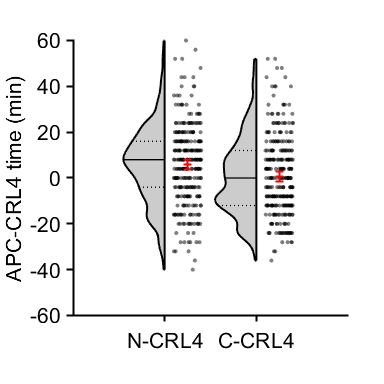


figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot(data_vals,'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1]);
xticklabels({'N-CRL4', 'C-CRL4'})
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (data_vals), 10,'k','filled','MarkerFaceAlpha',.5);
errorbar([1 2]+.25, m(1:2), sem(1:2),'+r','LineWidth',1.5)
ylabel('APC-CRL4 time (min)')
% ylim([0 40])
% yticks([0:10:60])
xlabel(' ')
% xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\APC-CRL.pdf'])

**Plot example traces whole cell cycle**

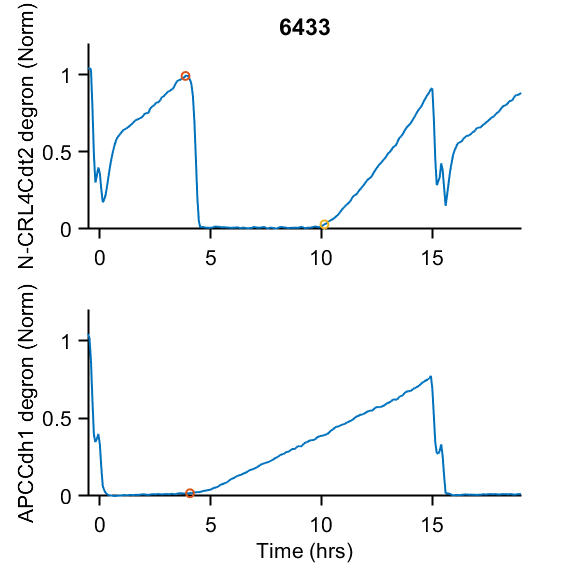

conds = [1];
rng(1)

for j = 1:length(conds)
    cond = conds(j);
    start_time = S(cond).POI(:,1) / framesPerHr;
    s_start = S(cond).POI(:,4)/ framesPerHr;
    end_time = S(cond).traceStats(:,2)/ framesPerHr;
    total = end_time - start_time;
    g1_length = s_start - start_time;
    
    
    inds = start_time < 2  & g1_length  < nanmedian(g1_length) + .5 & g1_length > nanmedian(g1_length) - .5 & total > 14;
    cells = find(inds);
    cells = [6433; 6433];
    for numcell = randsample(cells,min([1 length(cells)]))'
      trace = S(cond).crlArea(numcell,:) - min(S(cond).crlArea(numcell,:));
        trace = trace/trace(S(cond).POI(numcell,4));
        
        frames = S(cond).POI(numcell,1):S(cond).traceStats(numcell,2);
        offset = 10;
        frames = S(cond).POI(numcell,1)-offset:numFrames;
        time = (1:length(frames))/framesPerHr - offset/framesPerHr;
        apctrace = nansmoothm(S(cond).apcAreaNormM(numcell,frames)/max(S(cond).apcAreaNormM(numcell,frames)),5,'sgolay');
        trace = nansmoothm(trace(frames),5,'sgolay');
        
        figure('units','inches','position',[0 0 6 6])
        tiledlayout(2,1), hold on
        nexttile, hold on
        plot(time,trace)
        point_time = S(cond).POI(numcell,4)-S(cond).POI(numcell,1)+offset;
        scatter(time(point_time),trace(point_time),'LineWidth',1.5)
        point_time = 10*15+2+offset;
        scatter(time(point_time),trace(point_time),'LineWidth',1.5)
        ylabel('N-CRL4Cdt2 degron (Norm)')
        ylim([0 1.2])
        xlim([-8/framesPerHr max(time)])
        title(num2str(numcell))
        
%         div = (S(cond).traceStats(numcell,2) - S(cond).POI(numcell,1))/framesPerHr;
%         rectangle('Position',[-.4 0 1 1.2],'FaceColor',[.8 .8 .8],'EdgeColor','none')
%         rectangle('Position',[div-.4 0  1 1.2],'FaceColor',[.8 .8 .8],'EdgeColor','none')
        
        nexttile, hold on
        plot(time, apctrace)
        point_time = S(cond).POI(numcell,2)-S(cond).POI(numcell,1)+offset;
        scatter(time(point_time),apctrace(point_time),'LineWidth',1.5)
        ylim([0 1.2])
        xlim([-8/framesPerHr max(time)])
        %     vline([])
        xlabel('Time (hrs)')
        ylabel('APCCdh1 degron (Norm)')
%         pbaspect([2 1 1])
%         div = (S(cond).traceStats(numcell,2) - S(cond).POI(numcell,1))/framesPerHr;
%         rectangle('Position',[-.4 0 1 1.2],'FaceColor',[.8 .8 .8],'EdgeColor','none')
%         rectangle('Position',[div-.4 0  1 1.2],'FaceColor',[.8 .8 .8],'EdgeColor','none')
        print_pdf([pwd() '\Figs\' num2str(j) '-cell' num2str(numcell) '-traces_stacked.pdf'])

    end
end

**Plot example traces whole cell cycle**

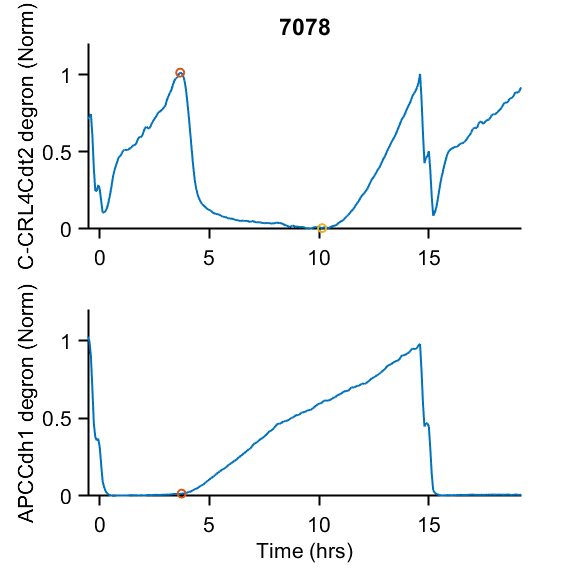

conds = [2];
rng(1)

for j = 1:length(conds)
    cond = conds(j);
    start_time = S(cond).POI(:,1) / framesPerHr;
    s_start = S(cond).POI(:,4)/ framesPerHr;
    end_time = S(cond).traceStats(:,2)/ framesPerHr;
    total = end_time - start_time;
    g1_length = s_start - start_time;
    
    
    inds = start_time < 2  & g1_length  < nanmedian(g1_length) + .5 & g1_length > nanmedian(g1_length) - .5 & total > 14.5;
    cells = find(inds);
    cells = [7078; 7078];
    for numcell = randsample(cells,min([1 length(cells)]))'
        trace = S(cond).crlArea(numcell,:) - min(S(cond).crlArea(numcell,:));
        trace = trace/trace(S(cond).POI(numcell,4));
        
        frames = S(cond).POI(numcell,1):S(cond).traceStats(numcell,2);
        offset = 10;
        frames = S(cond).POI(numcell,1)-offset:numFrames;
        time = (1:length(frames))/framesPerHr - offset/framesPerHr;
        apctrace = nansmoothm(S(cond).apcAreaNormM(numcell,frames)/max(S(cond).apcAreaNormM(numcell,frames)),5,'sgolay');
        trace = nansmoothm(trace(frames),5,'sgolay');
        
        figure('units','inches','position',[0 0 6 6])
        tiledlayout(2,1), hold on
        nexttile, hold on
        plot(time,trace)
        point_time = S(cond).POI(numcell,4)-S(cond).POI(numcell,1)+offset;
        scatter(time(point_time),trace(point_time),'LineWidth',1.5)
        point_time = 10*15+2+offset;
        scatter(time(point_time),trace(point_time),'LineWidth',1.5)
        ylabel('C-CRL4Cdt2 degron (Norm)')
        ylim([0 1.2])
        xlim([-8/framesPerHr max(time)])
        title(num2str(numcell))
        
%         div = (S(cond).traceStats(numcell,2) - S(cond).POI(numcell,1))/framesPerHr;
%         rectangle('Position',[-.4 0 1 1.2],'FaceColor',[.8 .8 .8],'EdgeColor','none')
%         rectangle('Position',[div-.4 0  1 1.2],'FaceColor',[.8 .8 .8],'EdgeColor','none')
        
        nexttile, hold on
        plot(time, apctrace)
        point_time = S(cond).POI(numcell,2)-S(cond).POI(numcell,1)+offset;
        scatter(time(point_time),apctrace(point_time),'LineWidth',1.5)
        ylim([0 1.2])
        xlim([-8/framesPerHr max(time)])
        %     vline([])
        xlabel('Time (hrs)')
        ylabel('APCCdh1 degron (Norm)')
%         pbaspect([2 1 1])
%         div = (S(cond).traceStats(numcell,2) - S(cond).POI(numcell,1))/framesPerHr;
%         rectangle('Position',[-.4 0 1 1.2],'FaceColor',[.8 .8 .8],'EdgeColor','none')
%         rectangle('Position',[div-.4 0  1 1.2],'FaceColor',[.8 .8 .8],'EdgeColor','none')
        print_pdf([pwd() '\Figs\' num2str(2) '-cell' num2str(numcell) '-traces_stacked.pdf'])

    end
end